# NanoLocz-lib Workbook - Automatic line profiling for width/height analysis

% This example demonstrates how to:
% - Load an AFM image
% - Apply background leveling
% - Detect peaks (particles) 
% - Measure particle sizes with automatic line profiling

## Load the AFM Image

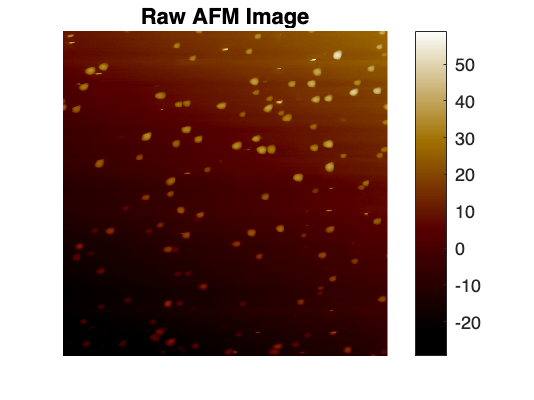

% Read AFM file (Bruker .spm format) and extract Height data
[im, ImageInfo] = ReadAFMFile('0.0_00003.spm','Height');

% Display the raw AFM image
figure;
imagesc(im);
axis image off;
afm_colormap('AFM brown')
colorbar;
title('Raw AFM Image');

## Level the Image (Background Flattening)

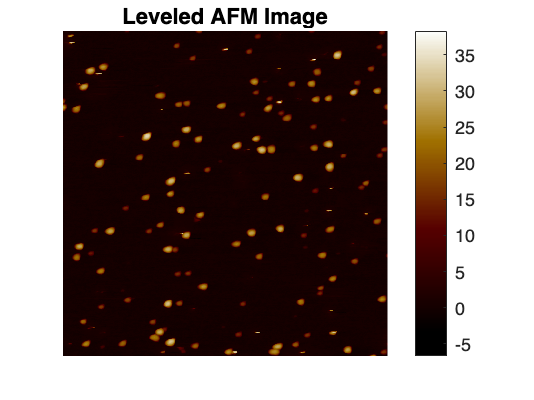

% Apply automated leveling using iterative peak-fitting method
im2 = level_auto(im,1,'iterative fit peaks');
% Display leveled image
figure;
imagesc(im2);
axis image off;
afm_colormap('AFM brown')
colorbar;
title('Leveled AFM Image');

## Preprocessing for Particle Detection

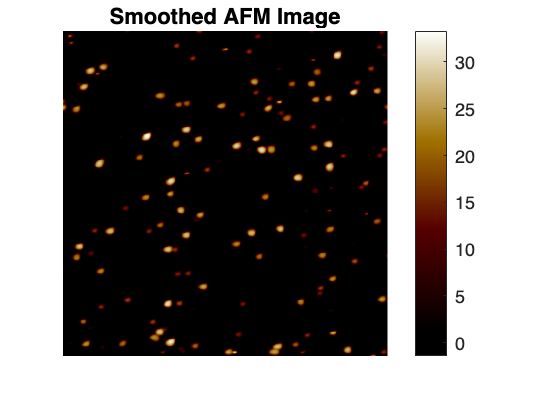

% Apply scar fill to remove thin horizontal scars/artifacts
im3 = scar_fill(im2, 0.05, 0.5, 3);
% Apply Gaussian smoothing to reduce noise
im3 = imgaussfilt(im3, 2);  
% Display smoothed image
figure;
imagesc(im3);
axis image off;
afm_colormap('AFM brown')
colorbar;
title('Smoothed AFM Image');

## Detect Peaks (Particles)

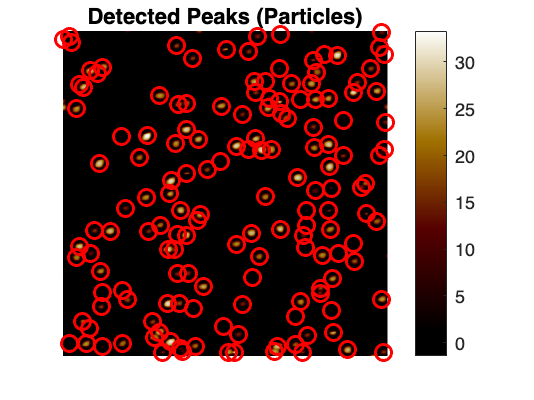

% Set detection parameters
thresh = 2;          % Minimum height threshold (nm)
kernel_size = 5;     % Local neighbourhood size (pixels)

% Run peak detection
locs = Fast_peaks2D(im3, thresh, kernel_size);

% Display detected peaks overlaid on image
figure;
imagesc(im3);
axis image off;
afm_colormap('AFM brown')
colorbar;
hold on;
plot(locs(:,1), locs(:,2), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
title('Detected Peaks (Particles)');

## Run Auto Profile for width analysis

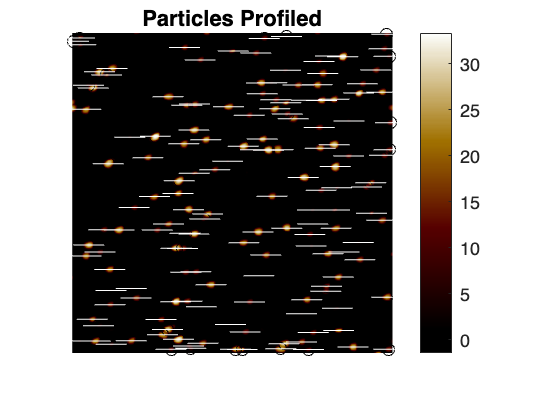

directions = [1, 1, 1, 1];  % enable all directions
max_radius = 50;
widthRef = 'z = 0';

[Rmin, Rmax, Rmean, p] = Lineprofiler(im3, locs(:,1:2), max_radius, directions, widthRef);

figure;
imagesc(im3); hold on;
axis image off;
afm_colormap('AFM brown')
colorbar;
plot(locs(:,1), locs(:,2), 'ko');
for j = 1:numel(locs(:,1))
    plot(p{j,1}(:,1), locs(j,2)*ones(size(p{j,1}(:,1))), 'w-'); % x-profiles
end
title('Particles Profiled');

## Plot width and hgith distributions

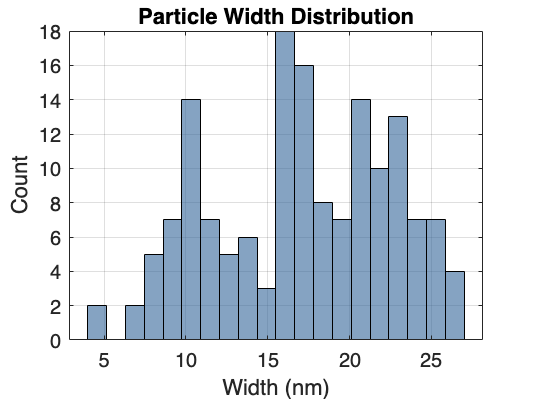

%% Plot Width and Height Distributions
widths = Rmean;
heights = locs(:,3);

% Plot Width Distribution
figure;
histogram(widths, 20, 'FaceColor', [0.2, 0.4, 0.6], 'EdgeColor', 'k');
xlabel('Width (nm)');
ylabel('Count');
title('Particle Width Distribution');
grid on;

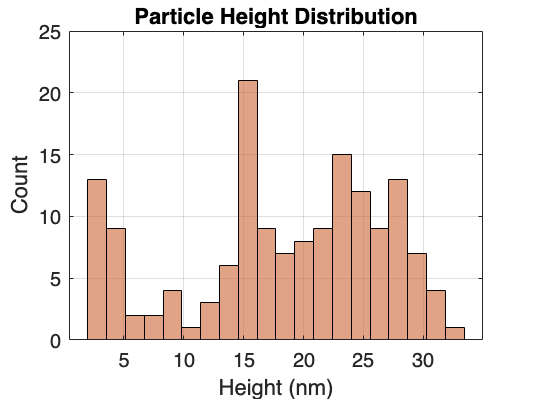


% Plot Height Distribution
figure;
histogram(heights, 20, 'FaceColor', [0.8, 0.4, 0.2], 'EdgeColor', 'k');
xlabel('Height (nm)');
ylabel('Count');
title('Particle Height Distribution');
grid on;

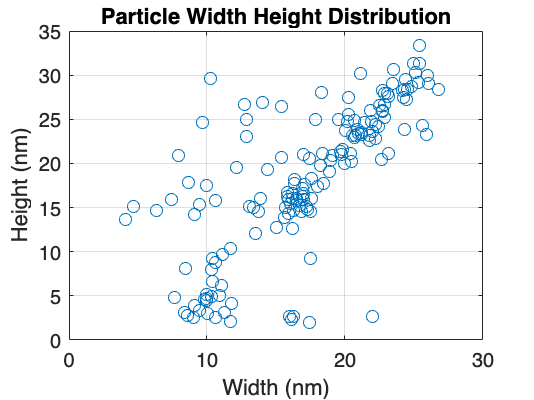


figure;
plot(widths,heights,'o')
xlabel('Width (nm)');
ylabel('Height (nm)');
title('Particle Width Height Distribution');
grid on;